# **Seconda Lezione**

### **Cicli**

x = [1; 2; 3; 4];
y = [5; 6; 7; 8];

%% Usando il prodotto scalare
x'*y

ans = 70

%% Usando il ciclo for
sum = 0;
vec_length = 4;
for i=1:vec_length
    sum = sum + x(i) * y(i);
end
sum

sum = 70

%% Usando il ciclo while
i = 1;
sum = 0;
while i <= vec_length
    sum = sum + x(i) * y(i);
    i = i + 1;
end
sum

sum = 70

%% If e else
r = randi([-5, 5]);
if r >= 0
    sqrt(r)
else
    % error("r is < 0")
end

ans = 2

### Operatori logici

% & and
1 & 0

ans = logical
   0


% | or
% ~ not

### Funzioni

Esistono 4 modi differenti per definire una funzione

- Comando `eval`

- Comando `inline`

- Anonimous functions

- Files `.m`

#### Anonimous functions

cubic = @(x) x.^3 - 1;
parabolic = @(x) (x-1).^2

parabolic = function_handle with value:
    @(x)(x-1).^2


x = 0:3;
cubic(x)

ans =     -1     0     7    26


parabolic(x)

ans =      1     0     1     4


% In più variabili
wave = @(x, y) sin(x) + cos(x .* y)

wave = function_handle with value:
    @(x,y)sin(x)+cos(x.*y)


% x = linspace(-3, 3, 100);
% y = linspace(-3, 3, 100);
% plot(x, y, wave(x, y))

### Plot

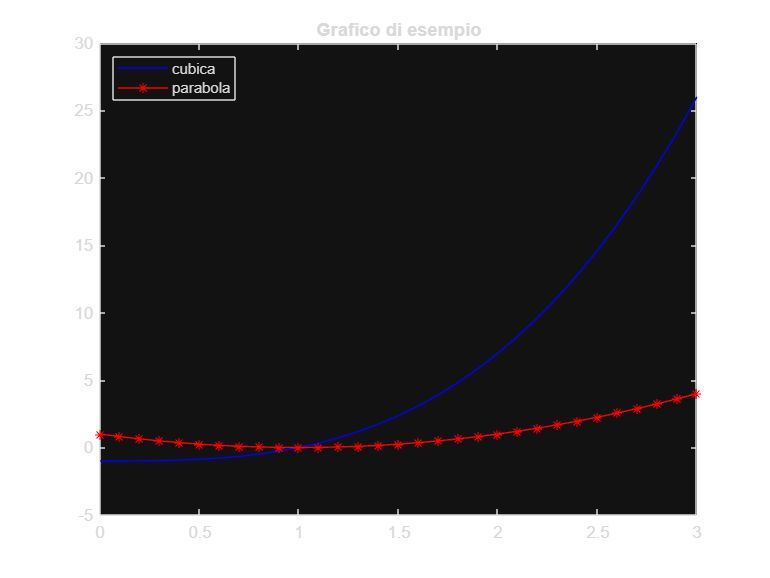

x = 0:.1:3;
plot(x, cubic(x), "b-")
hold on
grid on
plot(x, parabolic(x), "r-*")
legend("cubica", "parabola", "Location", "NorthWest")
title("Grafico di esempio")
hold off
grid off

#### In scala logaritmica

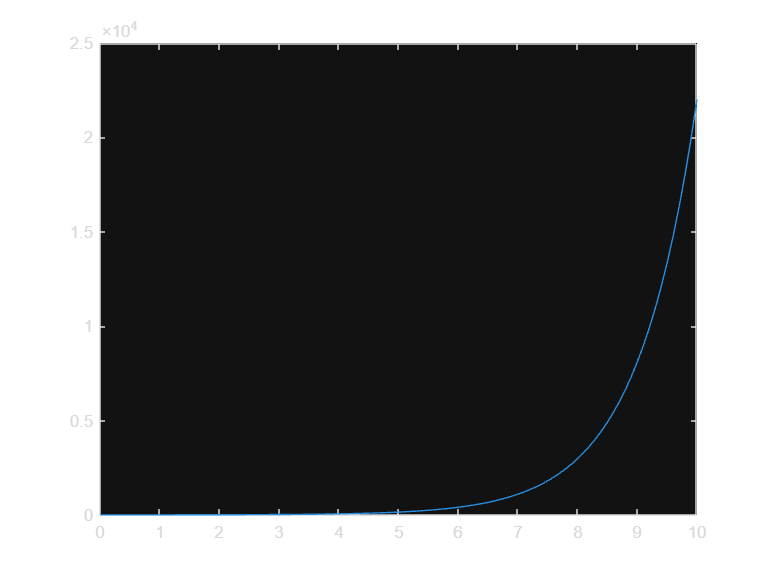

clc
clear
f = @(x) exp(x);
x = 0:0.1:10;
plot(x, f(x));

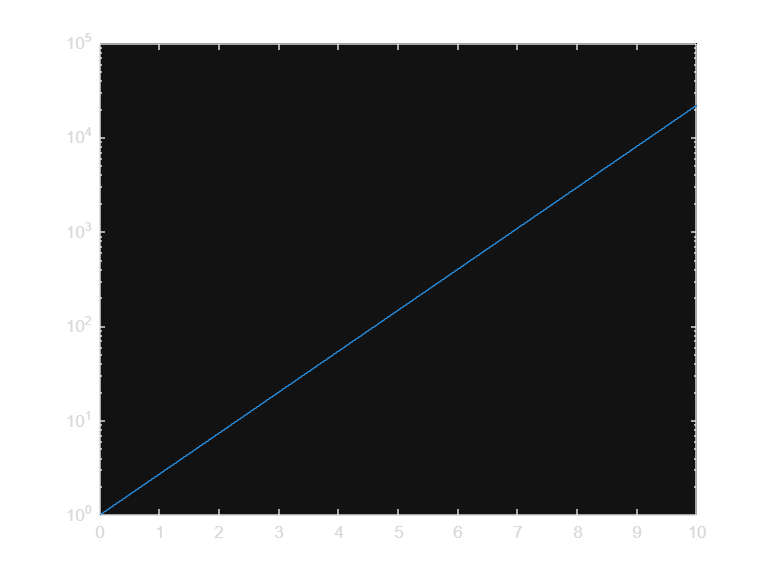

semilogy(x, f(x));

### Usando file

a = det2([1 2; 3 4])

a = -2